omega_WTR = linspace(0.5,0.9,10000); %*2*pi/60; % rad/s
time_omega_wtr = linspace(0,simtime,length(omega_WTR));
omega_WTR_n = 7.56*2*pi/60 % rad/s here it is the max rotor speed

omega_WTR_n = 0.7917

omega_WTR_sl = 0.78; % rad/s 
omega_WTR_min = 5*2*pi/60 % rad/s

omega_WTR_min = 0.5236

R_WTR = 117; % m
v_w_n = 10.59; % m/s
v_w_min = 3; % m/s
P_mppt_sl = 0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR_sl^3/15e6

P_mppt_sl = 0.8935

slope = (1-P_mppt_sl)/(omega_WTR_n-omega_WTR_sl)

slope = 9.1211


b = 1-slope*omega_WTR_n

b = -6.2210

slope*0.7915+b

ans = 0.9983

slope*0.7803

ans = 7.1172

slope*0.7803+b

ans = 0.8962

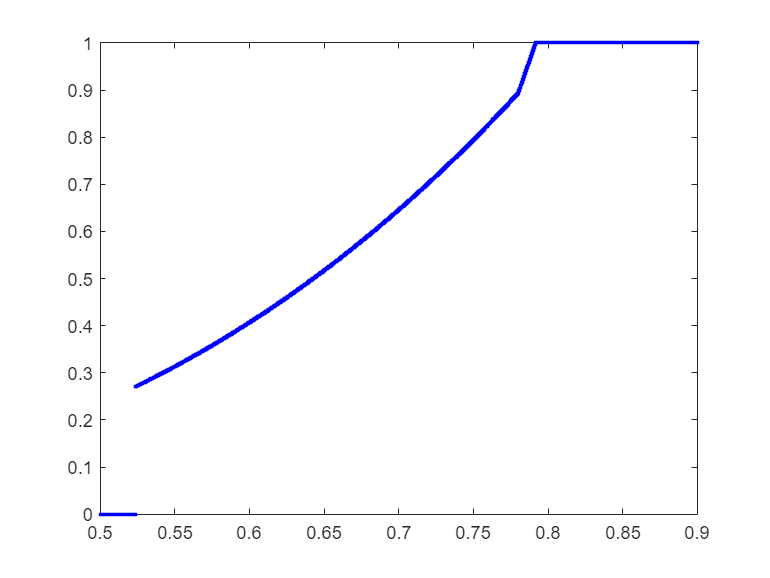

lambda_opt = 9;
cp_max = 0.489;

% omega_WTR(i)

rho = 1.2225;
P_MPPT = zeros(1,length(omega_WTR));
y= 0;
for i = 1:length(omega_WTR)
    y = 0;
    if omega_WTR(i) < omega_WTR_min
                y = 0;
    elseif omega_WTR(i) < omega_WTR_sl 
                y = (0.5*pi*rho*R_WTR^5*cp_max/lambda_opt^3*omega_WTR(i)^3)/15e6;
    elseif omega_WTR(i) < omega_WTR_n
                y = slope*omega_WTR(i)+b;
    else
                y = 1;
    end

    P_MPPT(i) = y ;
end
plot(omega_WTR,P_MPPT,'b.')


test_omega_wtr = [time_omega_wtr; omega_WTR]'

test_omega_wtr =          0    0.5000
    0.0100    0.5000
    0.0200    0.5001
    0.0300    0.5001
    0.0400    0.5002
    0.0500    0.5002
    0.0600    0.5002
    0.0700    0.5003
    0.0800    0.5003
    0.0900    0.5004
